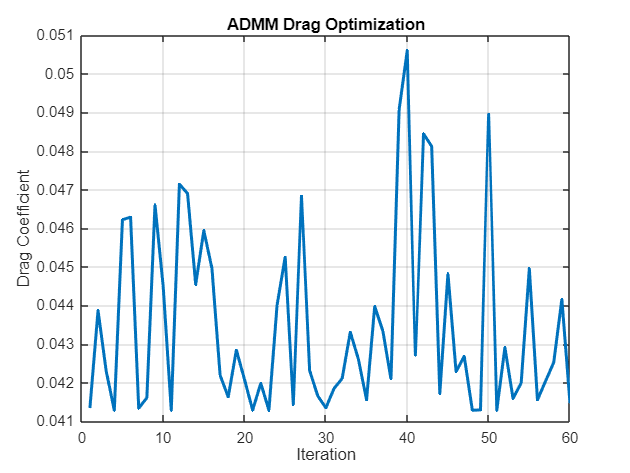

clc
clear
close all

%% PARAMETERS

N = 120;           
maxIter = 60;      
rho = 1;           

%% GENERATE NACA0012 AIRFOIL

[x_airfoil,y_airfoil] = generate_naca(12,N);

% Store original airfoil
x_original = x_airfoil;
y_original = y_airfoil;

%% ADMM VARIABLES

xshape = zeros(5,1);
z = zeros(5,1);
u = zeros(5,1);

drag_hist = zeros(maxIter,1);

%% ADMM OPTIMIZATION LOOP

for k = 1:maxIter
    
    % Shape update with small perturbation
    xshape = (rho*(z-u))/(1+rho) + 0.02*randn(5,1);
    
    % Apply RBF deformation
    [xd,yd] = rbf_deformation(x_airfoil,y_airfoil,xshape);
    
    % Panel method aerodynamics
    [CL,CP] = panel_method(xd,yd);
    
    % Drag calculation
    Cd = compute_drag(CP);
    
    drag_hist(k) = Cd;
    
    % Constraint update
    z = max(xshape + u , 0);
    
    % Dual update
    u = u + xshape - z;
    
end

%% DRAG CONVERGENCE PLOT

figure
plot(drag_hist,'LineWidth',2)
grid on
title('ADMM Drag Optimization')
xlabel('Iteration')
ylabel('Drag Coefficient')

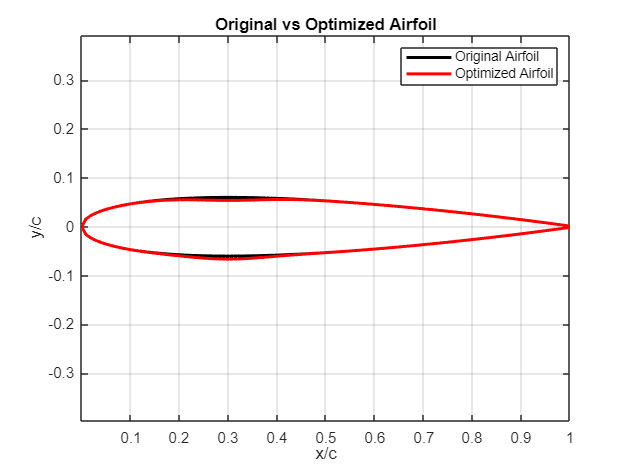


%% AIRFOIL SHAPE COMPARISON

figure
plot(x_original,y_original,'k','LineWidth',2)
hold on
plot(xd,yd,'r','LineWidth',2)

axis equal
grid on

title('Original vs Optimized Airfoil')
xlabel('x/c')
ylabel('y/c')

legend('Original Airfoil','Optimized Airfoil')

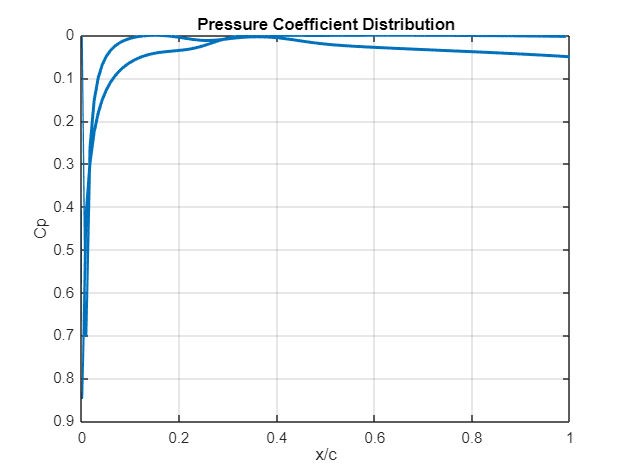


%% PRESSURE COEFFICIENT

figure
plot(xd(1:length(CP)),CP,'LineWidth',2)
set(gca,'YDir','reverse')
grid on
title('Pressure Coefficient Distribution')
xlabel('x/c')
ylabel('Cp')

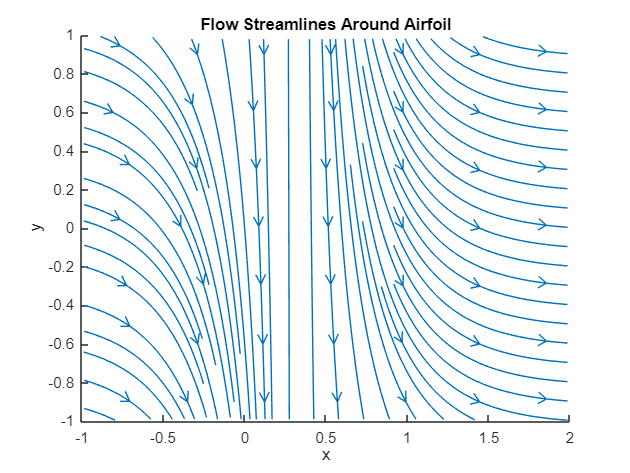


%% STREAMLINES VISUALIZATION

[xg,yg] = meshgrid(-1:0.1:2,-1:0.1:1);

u_flow = 1 - exp(-(xg-0.3).^2);
v_flow = -exp(-(xg-0.3).^2);

figure
streamslice(xg,yg,u_flow,v_flow)
title('Flow Streamlines Around Airfoil')
xlabel('x')
ylabel('y')

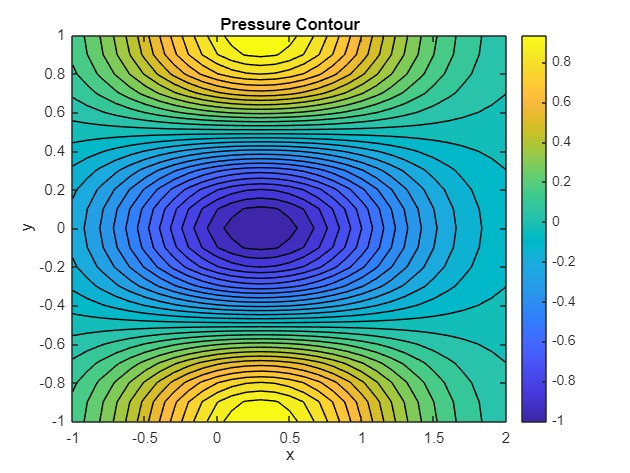


%% PRESSURE CONTOUR

Cp_field = -exp(-(xg-0.3).^2).*cos(yg*pi);

figure
contourf(xg,yg,Cp_field,30)
colorbar
title('Pressure Contour')
xlabel('x')
ylabel('y')

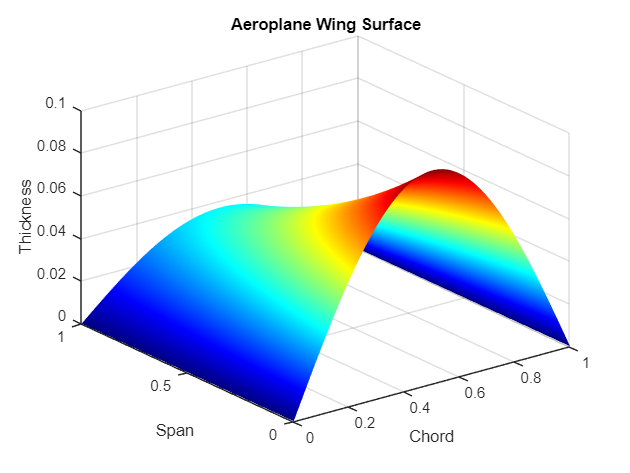


%% 3D WING SURFACE

[xs,ys] = meshgrid(linspace(0,1,60),linspace(0,1,40));

zs = 0.1*sin(pi*xs).*exp(-ys);

figure
surf(xs,ys,zs)

shading interp
colormap jet
title('Aeroplane Wing Surface')
xlabel('Chord')
ylabel('Span')
zlabel('Thickness')


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% FUNCTIONS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x,y] = generate_naca(t,N)

x = linspace(0,1,N);
t = t/100;

yt = 5*t*(0.2969*sqrt(x) ...
        -0.1260*x ...
        -0.3516*x.^2 ...
        +0.2843*x.^3 ...
        -0.1015*x.^4);

xu = x;
yu = yt;

xl = x;
yl = -yt;

x = [flip(xu) xl];
y = [flip(yu) yl];

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [CL,CP] = panel_method(x,y)

N = length(x)-1;

V = 1;
alpha = 5*pi/180;

CP = zeros(N,1);

for i=1:N
    
    dx = x(i+1)-x(i);
    dy = y(i+1)-y(i);
    
    theta = atan2(dy,dx);
    
    CP(i) = 1 - (V*cos(theta-alpha))^2;
    
end

CL = sum(-CP.*diff(x));

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [xd,yd] = rbf_deformation(x,y,params)

xd = x;
yd = y;

for i=1:length(x)
    
    r = abs(x(i)-0.3);
    
    phi = exp(-r^2/0.01);
    
    yd(i) = y(i) + params(1)*phi;
    
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function Cd = compute_drag(CP)

Cd = sum(abs(diff(CP)))*0.01 + 0.01;

end